# Model Predictive Control - Exam Assignment 2021

clear all; close all; clc;
addpath('Functions\')
addpath('Functions\Realization\')

# Initialization



Gamma1 = 0.60;  Gamma2 = 0.75;  % Minimum Phase System
% Gamma1 = 0.45;  Gamma2 = 0.40;  % Non-Minimum Phase System

[p,a,A,g,rho] = get_parameters(Gamma1,Gamma2); 

# Simulation time

t0 = 0.0;           % [s] Initial time
t_f = 20*60;        % [s] Final time
Ts = 4;             % [s] Sample time
t = [t0:Ts:t_f]';   % [s] Sample instants
T_plot = t';
Nsim = length(t);

# Inital values for Liquid mass

m10 = 0.0; % [g] Liquid mass in tank 1 at time t0
m20 = 0.0; % [g] Liquid mass in tank 2 at time t0
m30 = 0.0; % [g] Liquid mass in tank 3 at time t0
m40 = 0.0; % [g] Liquid mass in tank 4 at time t0

x0 = [m10; m20; m30; m40];

# Flow rates from pumps

F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 0.0; % Unknown stochastic variables (normal distributed) 
F4 = 0.0; % Unknown stochastic variables (normal distributed)

# Initial values for control inputs and stochastic variables

u = [F1 ; F2];
d = [F3(:,1) ; F4(:,1)];
u_rep = [repmat(F1,1,Nsim); repmat(F2,1,Nsim)];
d_rep = [repmat(F3,1,Nsim); repmat(F4,1,Nsim)];

u1 = 1.10*u_rep; % 10%, control signal 
u2 = 1.25*u_rep; % 25%, control signal
u3 = 1.50*u_rep; % 50%, control signal

# Steady states and initial guess of steady state for non-linear variables

% Steady states
xs0 = 5000*ones(4,1);       % Initial guess of steady state

us  = u;
xs  = fsolve(@ModifiedFourTankSystemWrap, xs0, [], u ,d , p); % Steady State


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ys  = FourTankSystemSensor(xs,p); % Get outputs
zs  = FourTankSystemOutput(xs,p); % Get measured outputs

% x0 = xs; % for 3.3 - 3.6
% x0 = [0 ; 0 ; 0 ; 0] % for 3.1 and 3.2

# Problem 3.1

% Solve the ordinary differential equations
[T1,X1] = ode15s(@ModifiedFourTankSystem,t,x0,[],u1(:,1),d(:,1),p);
[T2,X2] = ode15s(@ModifiedFourTankSystem,t,x0,[],u2(:,1),d(:,1),p);
[T3,X3] = ode15s(@ModifiedFourTankSystem,t,x0,[],u3(:,1),d(:,1),p);
X1 = X1';     X2 = X2';     X3 = X3';

% help variables
[nT1,nX1] = size(X1);    [nT2,nX2] = size(X2);    [nT3,nX3] = size(X3);

% Compute the measured variables
y10 = zeros(nT1,nX1);    y25 = zeros(nT2,nX2);    y50 = zeros(nT3,nX3);

for i=1:nX1
y10(:,i) = FourTankSystemSensorUnit(X1(:,i),p);
end

for i=1:nX2
y25(:,i) = FourTankSystemSensorUnit(X2(:,i),p);
end

for i=1:nX3
y50(:,i) = FourTankSystemSensorUnit(X3(:,i),p);
end

# Plots for 3.1

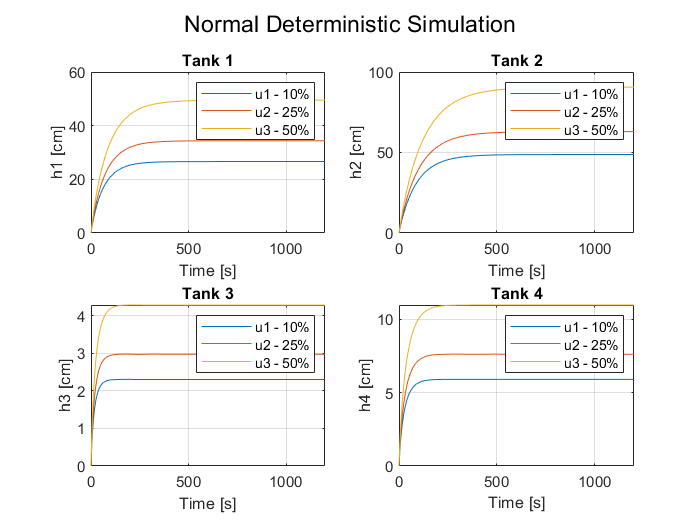

figure; % Change of height
sgtitle('Normal Deterministic Simulation') 
subplot(2,2,1);
plot(T1,y10(1,:)); hold on; plot(T2,y25(1,:)); hold on; plot(T3,y50(1,:)); hold off; 
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h1 [cm]'); xlabel('Time [s]')
title('Tank 1'); xlim([0 1200]); grid; 

subplot(2,2,2);
plot(T1,y10(2,:)); hold on; plot(T2,y25(2,:)); hold on; plot(T3,y50(2,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h2 [cm]'); xlabel('Time [s]')
title('Tank 2'); xlim([0 1200]); grid; 

subplot(2,2,3);
plot(T1,y10(3,:)); hold on; plot(T2,y25(3,:)); hold on; plot(T3,y50(3,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h3 [cm]'); xlabel('Time [s]')
title('Tank 3'); xlim([0 1200]); grid; 

subplot(2,2,4);
plot(T1,y10(4,:)); hold on; plot(T2,y25(4,:)); hold on; plot(T3,y50(4,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h4 [cm]'); xlabel('Time [s]')
title('Tank 4'); xlim([0 1200]); grid; 

# Problem 3.2

% Noise variance
% Qe = diag([2^2 2^2]);           % Process noise       (low)
Qe = diag([3^2 3^2]);           % Process noise     (medium)
% Qe = diag([5^2 5^2]);           % Process noise     (high)
% Rv = diag([2^2 2^2 2^2 2^2]);   % Measurement noise   (low)
Rv = diag([3^2 3^2 3^2 3^2]);   % Measurement noise (medium)
% Rv = diag([5^2 5^2 5^2 5^2]);   % Measurement noise (high)

% Generate noise vector
qe = chol(Qe,'lower');  rv = chol(Rv,'lower');

W1 = qe*randn(2,Nsim);     % Process noise
W2 = qe*randn(2,Nsim);     % Process noise
W3 = qe*randn(2,Nsim);     % Process noise

V1  = rv*randn(4,Nsim);     % Measurement noise
V2  = rv*randn(4,Nsim);     % Measurement noise
V3  = rv*randn(4,Nsim);     % Measurement noise

% pre-allocate memory for storing results 
   nx = 4;               nu = 2;               ny = 4;             nz = 2;
   x1 = zeros(nx,Nsim);     x2 = zeros(nx,Nsim);     x3 = zeros(nx,Nsim); 
y10_2 = zeros(ny,Nsim);  y25_2 = zeros(ny,Nsim);  y50_2 = zeros(ny,Nsim);
z10_2 = zeros(nz,Nsim);  z25_2 = zeros(nz,Nsim);  z50_2 = zeros(nz,Nsim); 

X1 = zeros(1,nx); T1 = zeros(1,1);
X2 = zeros(1,nx); T2 = zeros(1,1);
X3 = zeros(1,nx); T3 = zeros(1,1);

x1(:,1) = x0;  x2(:,1) = x0;  x3(:,1) = x0;

for k=1:Nsim-1
[Tk1,Xk1] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x1(:,k),[],u1(:,k)+W1(:,k),d_rep(:,k),p);
[Tk2,Xk2] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x2(:,k),[],u2(:,k)+W2(:,k),d_rep(:,k),p);
[Tk3,Xk3] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x3(:,k),[],u3(:,k)+W3(:,k),d_rep(:,k),p);

x1(:,k+1) = Xk1(end,:)';  x2(:,k+1) = Xk2(end,:)';  x3(:,k+1) = Xk3(end,:)';

T1 = [T1; Tk1(end,:)'];  T2 = [T2; Tk2(end,:)'];  T3 = [T3; Tk3(end,:)'];
end

X1 = x1;  X2 = x2;  X3 = x3;

% help variables
[nT1,nX1] = size(x1);  [nT2,nX2] = size(x2);  [nT3,nX3] = size(x3);

for k=1:nX1
y10_2(:,k) = FourTankSystemSensorUnit(x1(:,k),p) + V1(:,k);
z10_2(:,k) = FourTankSystemOutputUnit(x1(:,k),p);
end

for k=1:nX2
y25_2(:,k) = FourTankSystemSensorUnit(x2(:,k),p) + V2(:,k);
z25_2(:,k) = FourTankSystemOutputUnit(x2(:,k),p);
end

for k=1:nX3
y50_2(:,k) = FourTankSystemSensorUnit(x3(:,k),p) + V3(:,k);
z50_2(:,k) = FourTankSystemOutputUnit(x3(:,k),p);
end

# Plots for 3.2

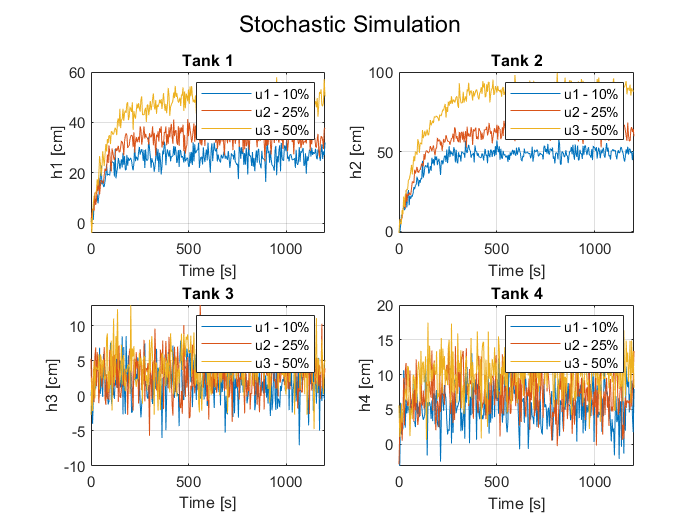

figure; % Change of height
sgtitle('Stochastic Simulation') 
subplot(2,2,1);
plot(T1,y10_2(1,:)); hold on; plot(T2,y25_2(1,:)); hold on; plot(T3,y50_2(1,:)); hold off; 
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h1 [cm]'); xlabel('Time [s]')
title('Tank 1'); xlim([0 1200]); grid; 

subplot(2,2,2);
plot(T1,y10_2(2,:)); hold on; plot(T2,y25_2(2,:)); hold on; plot(T3,y50_2(2,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h2 [cm]'); xlabel('Time [s]')
title('Tank 2'); xlim([0 1200]); grid; 

subplot(2,2,3);
plot(T1,y10_2(3,:)); hold on; plot(T2,y25_2(3,:)); hold on; plot(T3,y50_2(3,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h3 [cm]'); xlabel('Time [s]')
title('Tank 3'); xlim([0 1200]); grid; 

subplot(2,2,4);
plot(T1,y10_2(4,:)); hold on; plot(T2,y25_2(4,:)); hold on; plot(T3,y50_2(4,:)); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h4 [cm]'); xlabel('Time [s]')
title('Tank 4'); xlim([0 1200]); grid; 

# Problem 3.3


$$y_{norm} = \frac{y-y_{ss}}{u-u_{ss}}$$


x0 = xs;

% Solve the ordinary differential equations
[T1,X1] = ode15s(@ModifiedFourTankSystem,t,x0,[],u1(:,1),d(:,1),p);
[T2,X2] = ode15s(@ModifiedFourTankSystem,t,x0,[],u2(:,1),d(:,1),p);
[T3,X3] = ode15s(@ModifiedFourTankSystem,t,x0,[],u3(:,1),d(:,1),p);
X1 = X1';     X2 = X2';     X3 = X3';

% help variables
[nT1,nX1] = size(X1);    [nT2,nX2] = size(X2);    [nT3,nX3] = size(X3);

% Compute the measured variables
y10 = zeros(nT1,nX1);    y25 = zeros(nT2,nX2);    y50 = zeros(nT3,nX3);

for i=1:nX1
y10(:,i) = FourTankSystemSensorUnit(X1(:,i),p);
end

for i=1:nX2
y25(:,i) = FourTankSystemSensorUnit(X2(:,i),p);
end

for i=1:nX3
y50(:,i) = FourTankSystemSensorUnit(X3(:,i),p);
end

% Deterministic
y10_t1_num = y10(1,:)-ys(1);
y10_t1_den = u1(1,1)-us(1,1);
yd_norm_tank1_10 = y10_t1_num ./ y10_t1_den;

y10_t2_num = (y10(2,:)-ys(2));
y10_t2_den = (u1(2,1)-us(2,1));
yd_norm_tank2_10 = y10_t2_num ./ y10_t2_den;

y10_t3_num = (y10(3,:)-ys(3));
y10_t3_den = (u1(2,1)-us(2,1));
yd_norm_tank3_10 = y10_t3_num ./ y10_t3_den;

y10_t4_num = (y10(4,:)-ys(4));
y10_t4_den = (u1(1,1)-us(1,1));
yd_norm_tank4_10 = y10_t4_num ./ y10_t4_den;

% % Use these as inputs and outputs for the estimation toolbox
% y10_est_t1_num = (y10_t1_num+ys(1))';
% y10_est_t1_den = ones(301,1)*y10_t1_den+us(1,1);
% % y10_est_t1_num = (y10_t1_num)';
% % y10_est_t1_den = ones(301,1)*y10_t1_den;
% 
% y10_est_t2_num = (y10_t2_num+ys(2))';
% y10_est_t2_den = ones(301,1)*y10_t2_den+us(2,1);
% % y10_est_t2_num = (y10_t2_num)';
% % y10_est_t2_den = ones(301,1)*y10_t2_den;
% 
% y10_est_t3_num = (y10_t1_num+ys(1))';
% y10_est_t3_den = ones(301,1)*y10_t3_den+us(2,1);
% % y10_est_t3_num = (y10_t1_num)';
% % y10_est_t3_den = ones(301,1)*y10_t3_den;
% 
% y10_est_t4_num = (y10_t1_num+ys(1))';
% y10_est_t4_den = ones(301,1)*y10_t4_den+us(1,1);
% % y10_est_t4_num = (y10_t1_num)';
% % y10_est_t4_den = ones(301,1)*y10_t4_den;

yd_norm_tank1_25 = (y25(1,:)-ys(1)) ./ (u2(1,1)-us(1,1));
yd_norm_tank2_25 = (y25(2,:)-ys(2)) ./ (u2(2,1)-us(2,1));
yd_norm_tank3_25 = (y25(3,:)-ys(3)) ./ (u2(2,1)-us(2,1));
yd_norm_tank4_25 = (y25(4,:)-ys(4)) ./ (u2(1,1)-us(1,1));

yd_norm_tank1_50 = (y50(1,:)-ys(1)) ./ (u3(1,1)-us(1,1));
yd_norm_tank2_50 = (y50(2,:)-ys(2)) ./ (u3(2,1)-us(2,1));
yd_norm_tank3_50 = (y50(3,:)-ys(3)) ./ (u3(2,1)-us(2,1));
yd_norm_tank4_50 = (y50(4,:)-ys(4)) ./ (u3(1,1)-us(1,1));

# Plots for 3.3

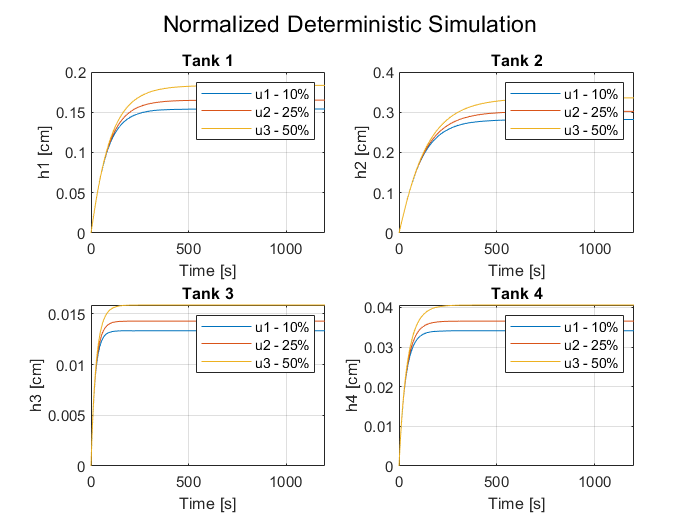

figure; % Change of height
sgtitle('Normalized Deterministic Simulation') 
subplot(2,2,1);
plot(T1,yd_norm_tank1_10); hold on; plot(T2,yd_norm_tank1_25); hold on; plot(T3,yd_norm_tank1_50); hold off; 
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h1 [cm]'); xlabel('Time [s]')
title('Tank 1'); xlim([0 1200]); grid; 

subplot(2,2,2);
plot(T1,yd_norm_tank2_10); hold on; plot(T2,yd_norm_tank2_25); hold on; plot(T3,yd_norm_tank2_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h2 [cm]'); xlabel('Time [s]')
title('Tank 2'); xlim([0 1200]); grid; 

subplot(2,2,3);
plot(T1,yd_norm_tank3_10); hold on; plot(T2,yd_norm_tank3_25); hold on; plot(T3,yd_norm_tank3_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h3 [cm]'); xlabel('Time [s]')
title('Tank 3'); xlim([0 1200]); grid; 

subplot(2,2,4);
plot(T1,yd_norm_tank4_10); hold on; plot(T2,yd_norm_tank4_25); hold on; plot(T3,yd_norm_tank4_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h4 [cm]'); xlabel('Time [s]')
title('Tank 4'); xlim([0 1200]); grid; 

# Problem 3.4


$$Y = GU$$


% pre-allocate memory for storing results 
   nx = 4;               nu = 2;               ny = 4;             nz = 2;
   x1 = zeros(nx,Nsim);     x2 = zeros(nx,Nsim);     x3 = zeros(nx,Nsim); 
y10_2 = zeros(ny,Nsim);  y25_2 = zeros(ny,Nsim);  y50_2 = zeros(ny,Nsim);
z10_2 = zeros(nz,Nsim);  z25_2 = zeros(nz,Nsim);  z50_2 = zeros(nz,Nsim); 

X1 = zeros(1,nx); T1 = zeros(1,1);
X2 = zeros(1,nx); T2 = zeros(1,1);
X3 = zeros(1,nx); T3 = zeros(1,1);

x1(:,1) = x0;  x2(:,1) = x0;  x3(:,1) = x0;

for k=1:Nsim-1
[Tk1,Xk1] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x1(:,k),[],u1(:,k)+W1(:,k),d_rep(:,k),p);
[Tk2,Xk2] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x2(:,k),[],u2(:,k)+W2(:,k),d_rep(:,k),p);
[Tk3,Xk3] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x3(:,k),[],u3(:,k)+W3(:,k),d_rep(:,k),p);

x1(:,k+1) = Xk1(end,:)';  x2(:,k+1) = Xk2(end,:)';  x3(:,k+1) = Xk3(end,:)';

T1 = [T1; Tk1(end,:)'];  T2 = [T2; Tk2(end,:)'];  T3 = [T3; Tk3(end,:)'];
end

X1 = x1;  X2 = x2;  X3 = x3;

% help variables
[nT1,nX1] = size(x1);  [nT2,nX2] = size(x2);  [nT3,nX3] = size(x3);

for k=1:nX1
y10_2(:,k) = FourTankSystemSensorUnit(x1(:,k),p) + V1(:,k);
z10_2(:,k) = FourTankSystemOutputUnit(x1(:,k),p);
end

for k=1:nX2
y25_2(:,k) = FourTankSystemSensorUnit(x2(:,k),p) + V2(:,k);
z25_2(:,k) = FourTankSystemOutputUnit(x2(:,k),p);
end

for k=1:nX3
y50_2(:,k) = FourTankSystemSensorUnit(x3(:,k),p) + V3(:,k);
z50_2(:,k) = FourTankSystemOutputUnit(x3(:,k),p);
end

# Plots for the stochastic part in 3.3

% Stochastic 
y_norm_tank1_10 = (y10_2(1,:)-ys(1)) ./ (u1(1,1)-us(1,1));
y_norm_tank2_10 = (y10_2(2,:)-ys(2)) ./ (u1(2,1)-us(2,1));
y_norm_tank3_10 = (y10_2(3,:)-ys(3)) ./ (u1(2,1)-us(2,1));
y_norm_tank4_10 = (y10_2(4,:)-ys(4)) ./ (u1(1,1)-us(1,1));

y_norm_tank1_25 = (y25_2(1,:)-ys(1)) ./ (u2(1,1)-us(1,1));
y_norm_tank2_25 = (y25_2(2,:)-ys(2)) ./ (u2(2,1)-us(2,1));
y_norm_tank3_25 = (y25_2(3,:)-ys(3)) ./ (u2(2,1)-us(2,1));
y_norm_tank4_25 = (y25_2(4,:)-ys(4)) ./ (u2(1,1)-us(1,1));

y_norm_tank1_50 = (y50_2(1,:)-ys(1)) ./ (u3(1,1)-us(1,1));
y_norm_tank2_50 = (y50_2(2,:)-ys(2)) ./ (u3(2,1)-us(2,1));
y_norm_tank3_50 = (y50_2(3,:)-ys(3)) ./ (u3(2,1)-us(2,1));
y_norm_tank4_50 = (y50_2(4,:)-ys(4)) ./ (u3(1,1)-us(1,1));

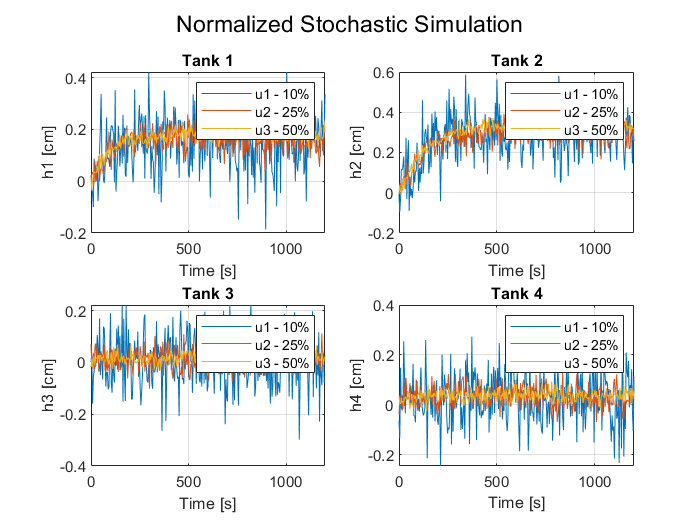

figure; % Change of height
sgtitle('Normalized Stochastic Simulation') 
subplot(2,2,1);
plot(T1,y_norm_tank1_10); hold on; plot(T2,y_norm_tank1_25); hold on; plot(T3,y_norm_tank1_50); hold off; 
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h1 [cm]'); xlabel('Time [s]')
title('Tank 1'); xlim([0 1200]); grid; 

subplot(2,2,2);
plot(T1,y_norm_tank2_10); hold on; plot(T2,y_norm_tank2_25); hold on; plot(T3,y_norm_tank2_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h2 [cm]'); xlabel('Time [s]')
title('Tank 2'); xlim([0 1200]); grid; 

subplot(2,2,3);
plot(T1,y_norm_tank3_10); hold on; plot(T2,y_norm_tank3_25); hold on; plot(T3,y_norm_tank3_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h3 [cm]'); xlabel('Time [s]')
title('Tank 3'); xlim([0 1200]); grid; 

subplot(2,2,4);
plot(T1,y_norm_tank4_10); hold on; plot(T2,y_norm_tank4_25); hold on; plot(T3,y_norm_tank4_50); hold off;
legend('u1 - 10%', 'u2 - 25%', 'u3 - 50%'); ylabel('h4 [cm]'); xlabel('Time [s]')
title('Tank 4'); xlim([0 1200]); grid; 

### TF's for 3.4?

$B = \left[\matrix{\gamma_1 & 0 \cr 0 & \frac{\gamma_2 k_2}{A_2} \cr 0 & \frac{(1-\gamma_2)k_2}{A_3} \cr \frac{(1-\gamma_1)k_1}{A_4} & 0}\right]$ and $C = \left[ \matrix{k_c & 0 & 0 & 0 \cr 0 & k_c & 0 & 0} \right]$ according to Johanson2000 but from IRJET-V3I6400.pdf we get a bit different

[Ac,Bc,Cc,Cz,Ec] = get_linearizedModel(p,xs);
sys = ss(Ac,Bc,Cc,0);

% yd_norm_tank1_10 = yd_norm_tank1_10 + ys;
% yd_norm_tank1_10 = yd_norm_tank2_10 + ys;

tau1 = (A(1)/a(1))*(sqrt(2*yd_norm_tank1_10(1,end))/g);
tau2 = (A(2)/a(2))*(sqrt(2*yd_norm_tank1_10(1,end))/g);
tau3 = (A(3)/a(3))*(sqrt(2*yd_norm_tank2_10(1,end))/g);
tau4 = (A(4)/a(4))*(sqrt(2*yd_norm_tank2_10(1,end))/g);
% tau1 = (A(1)*sqrt(2*g*yd_norm_tank1_10(1,end)))/(a(1)*g);
% tau2 = (A(2)*sqrt(2*g*yd_norm_tank1_10(1,end)))/(a(2)*g);
% tau3 = (A(3)*sqrt(2*g*yd_norm_tank2_10(1,end)))/(a(3)*g);
% tau4 = (A(4)*sqrt(2*g*yd_norm_tank2_10(1,end)))/(a(4)*g);

k1 = 3.1; % cm^3/s
k2 = 3.3; % cm^3/s
% k1 = 0.1;
% k2 = 0.1;
kc = Cc(1,1);
c1 = (tau1*k1*kc)/A(1);
c2 = (tau2*k2*kc)/A(2);
% c1 = 1; c2 = 1;
% c1 = 0.103526/Gamma1
% c2 = 0.175104/Gamma2

s = tf('s');
G11 = (Gamma1*c1*k1)/(1+(tau1*s))

G11 =
 
   6.993e-06
  ------------
  0.1753 s + 1
 
Continuous-time transfer function.



G12 = zpk(((1-Gamma2)*c1)/((1+s*tau3)*(1+s*tau1)))

G12 =
 
      2.2619e-05
  -------------------
  (s+5.706) (s+4.217)
 
Continuous-time zero/pole/gain model.



G21 = zpk(((1-Gamma1)*c2)/((1+s*tau4)*(1+s*tau2)))

G21 =
 
      3.8525e-05
  -------------------
  (s+5.706) (s+4.217)
 
Continuous-time zero/pole/gain model.



G22 = (Gamma2*c2)/(1+(s*tau2))

G22 =
 
   3.002e-06
  ------------
  0.1753 s + 1
 
Continuous-time transfer function.



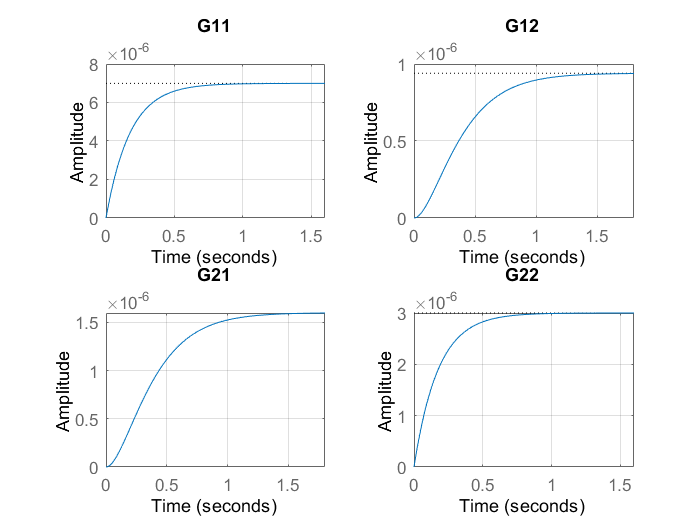

% k1 = 1; k2 = 1;

% tau1 = (A(1)*sqrt(2*g*ys(1,1)))/(a(1)*g);
% tau2 = (A(2)*sqrt(2*g*ys(2,1)))/(a(2)*g);
% tau3 = (A(3)*sqrt(2*g*ys(3,1)))/(a(3)*g);
% tau4 = (A(4)*sqrt(2*g*ys(4,1)))/(a(4)*g);
% C1 = (tau1*k1/A(1))*sqrt(2*ys(1,1)/g)
% C2 = (tau2*k2/A(2))*sqrt(2*ys(2,1)/g)

% tau1 = (A(1)*sqrt(2*g*yd_norm_tank1_10(1,end)))/(a(1)*g);
% tau2 = (A(2)*sqrt(2*g*yd_norm_tank2_10(1,end)))/(a(2)*g);
% tau3 = (A(3)*sqrt(2*g*yd_norm_tank3_10(1,end)))/(a(3)*g);
% tau4 = (A(4)*sqrt(2*g*yd_norm_tank4_10(1,end)))/(a(4)*g);
% C1 = (tau1*k1/A(1))*sqrt(2*yd_norm_tank1_10(1,end)/g)
% C2 = (tau2*k2/A(2))*sqrt(2*yd_norm_tank2_10(1,end)/g)

% We cannot see from plots in 3.3 if the tf's are 2nd or 1st order. 
% s = tf('s');
% G11 = (Gamma1*C1)/((tau1*s)+1)
% G12 = ((1-Gamma2)*C1)/((tau1*s+1)*(tau3*s+1))
% G21 = ((1-Gamma1)*C2)/((tau2*s+1)*(tau4*s+1))
% G22 = (Gamma2*C2)/((tau2*s)+1)


figure;
subplot(2,2,1)
step(G11);title('G11');grid on;
subplot(2,2,2)
step(G12);title('G12');grid on;
subplot(2,2,3)
step(G21);title('G21');grid on;
subplot(2,2,4)
step(G22);title('G22');grid on;

### Proof

% Proof of why we cannot see it in the plots in 3.3 if the tf's are 2nd or 1st
% order
G = tf(sys)

G =
 
  From input 1 to output...
        0.001578
   1:  -----------
       s + 0.01524
 
                3.408e-05
   2:  ---------------------------
       s^2 + 0.04365 s + 0.0003649
 
   3:  0
 
        0.001052
   4:  -----------
       s + 0.03239
 
  From input 2 to output...
                3.408e-05
   1:  ---------------------------
       s^2 + 0.06706 s + 0.0007898
 
        0.001973
   2:  -----------
       s + 0.01127
 
        0.0006577
   3:  -----------
       s + 0.05182
 
   4:  0
 
Continuous-time transfer function.




G11= minreal(G(1,1)) 

G11 =
 
   0.001578
  -----------
  s + 0.01524
 
Continuous-time transfer function.



G21 =G(2,1) 

G21 =
 
           3.408e-05
  ---------------------------
  s^2 + 0.04365 s + 0.0003649
 
Continuous-time transfer function.



G31 = G(3,1) 

G31 =
 
  0
 
Static gain.



G41 = G(4,1)

G41 =
 
   0.001052
  -----------
  s + 0.03239
 
Continuous-time transfer function.



G12= G(1,2) 

G12 =
 
           3.408e-05
  ---------------------------
  s^2 + 0.06706 s + 0.0007898
 
Continuous-time transfer function.



G22= G(2,2) 

G22 =
 
   0.001973
  -----------
  s + 0.01127
 
Continuous-time transfer function.



G32= G(3,2) 

G32 =
 
   0.0006577
  -----------
  s + 0.05182
 
Continuous-time transfer function.



G42= G(4,2)

G42 =
 
  0
 
Static gain.




[w1, zeta1, p1] = damp(G11)

w1 = 0.0152

zeta1 = 1

p1 = -0.0152

Tau1 = 1./w1 

Tau1 = 65.6109

[z1,p1,k1] = zpkdata(G11)

z1 = 1×1 cell array
    {0×1 double}


p1 = 1×1 cell array
    {[-0.0152]}


k1 = 0.0016

G11 = zpk(z1,p1,k1,'DisplayFormat','timeconstant')

G11 =
 
   0.10356
  ----------
  (1+65.61s)
 
Continuous-time zero/pole/gain model.




[w2, zeta2, p2] = damp(G12)

w2 =     0.0152
    0.0518


zeta2 =      1
     1


p2 =    -0.0152
   -0.0518


Tau2 = 1./w2 

Tau2 =    65.6109
   19.2973


[z2,p2,k2] = zpkdata(G12)

z2 = 1×1 cell array
    {0×1 double}


p2 = 1×1 cell array
    {2×1 double}


k2 = 3.4081e-05

G12 = zpk(z2,p2,k2,'DisplayFormat','timeconstant')

G12 =
 
        0.04315
  --------------------
  (1+19.3s) (1+65.61s)
 
Continuous-time zero/pole/gain model.




[w3, zeta3, p3] = damp(G21)

w3 =     0.0113
    0.0324


zeta3 =      1
     1


p3 =    -0.0113
   -0.0324


Tau3 = 1./w3 

Tau3 =    88.7676
   30.8757


[z3,p3,k3] = zpkdata(G21)

z3 = 1×1 cell array
    {0×1 double}


p3 = 1×1 cell array
    {2×1 double}


k3 = 3.4081e-05

G21 = zpk(z3,p3,k3,'DisplayFormat','timeconstant')

G21 =
 
        0.093407
  ---------------------
  (1+30.88s) (1+88.77s)
 
Continuous-time zero/pole/gain model.




[w4, zeta4, p4] = damp(G22)

w4 = 0.0113

zeta4 = 1

p4 = -0.0113

Tau4 = 1./w4

Tau4 = 88.7676

[z4,p4,k4] = zpkdata(G22)

z4 = 1×1 cell array
    {0×1 double}


p4 = 1×1 cell array
    {[-0.0113]}


k4 = 0.0020

G22 = zpk(z4,p4,k4,'DisplayFormat','timeconstant')

G22 =
 
   0.17514
  ----------
  (1+88.77s)
 
Continuous-time zero/pole/gain model.



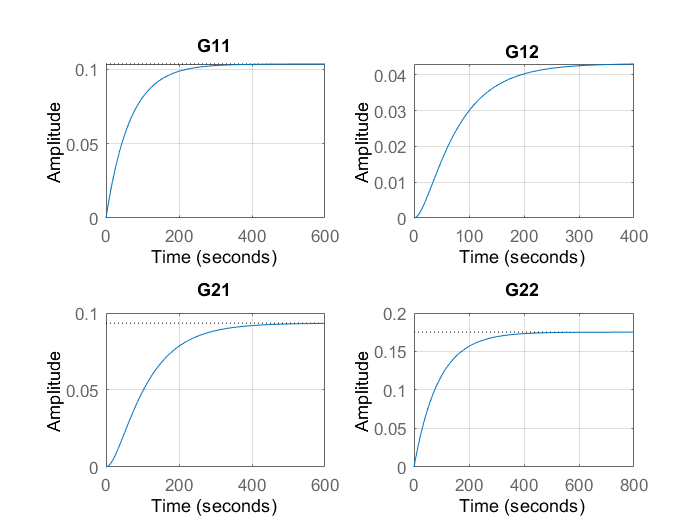



figure;
subplot(2,2,1)
step(G11);title('G11');grid on;
subplot(2,2,2)
step(G12);title('G12');grid on;
subplot(2,2,3)
step(G21);title('G21');grid on;
subplot(2,2,4)
step(G22);title('G22');grid on;

# Problem 3.5

% % Plot from system identification tool
% % The system identification tool has to be used before uncommenting this
% % code section

% Tfs from system identification tool for non-minimum phase
G11_id = tf([2.5537e-05],[1 0.0357]); 
G12_id = tf([3.6175e-06],[1 0.1814 0.0062]);
G21_id = tf([4.7166e-05],[1 2.6164 0.2028]);
G22_id = tf([1.7064e-05],[1 0.0873]);

% Tfs from the system identification tool for minimum phase

% G11_id = tf([2.483e-05],[1 0.0532]); 
% G12_id = tf([8.1455e-06],[1 0.3722 0.0174]);
% G21_id = tf([6.929e-06],[1 0.2419 0.0081]);
% G22_id = tf([3.267e-05],[1 0.0382]);

[z1_id,p1_id,k1_id] = zpkdata(G11_id);
G11_id = zpk(z1_id,p1_id,k1_id,'DisplayFormat','timeconstant')

G11_id =
 
  0.00071532
  ----------
  (1+28.01s)
 
Continuous-time zero/pole/gain model.



[z2_id,p2_id,k2_id] = zpkdata(G12_id);
G12 = zpk(z2_id,p2_id,k2_id,'DisplayFormat','timeconstant')

G12 =
 
       0.00058347
  ---------------------
  (1+7.368s) (1+21.89s)
 
Continuous-time zero/pole/gain model.



[z3_id,p3_id,k3_id] = zpkdata(G21_id);
G21_id = zpk(z3_id,p3_id,k3_id,'DisplayFormat','timeconstant')

G21_id =
 
        0.00023257
  ----------------------
  (1+0.3943s) (1+12.51s)
 
Continuous-time zero/pole/gain model.



[z4_id,p4_id,k4_id] = zpkdata(G22_id);
G22_id = zpk(z4_id,p4_id,k4_id,'DisplayFormat','timeconstant')

G22_id =
 
  0.00019546
  ----------
  (1+11.45s)
 
Continuous-time zero/pole/gain model.



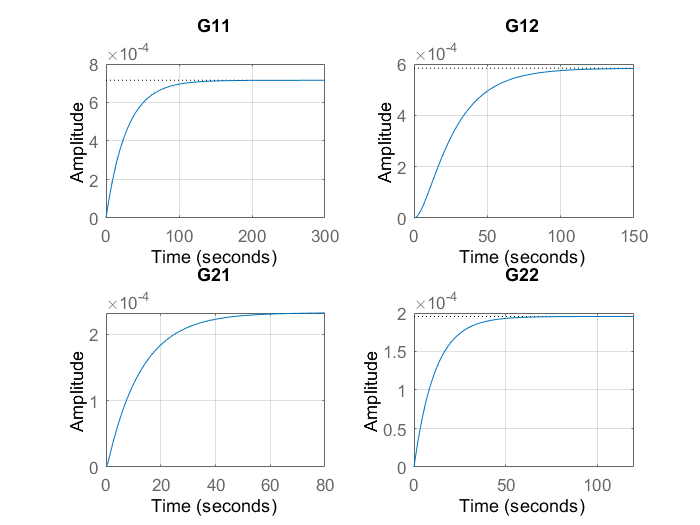


figure;
%sgtitle('Normalized Simulation from Estimation Tool') 
subplot(2,2,1)
step(G11_id);title('G11');grid on;
subplot(2,2,2)
step(G12_id);title('G12');grid on;
subplot(2,2,3)
step(G21_id);title('G21');grid on;
subplot(2,2,4)
step(G22_id);title('G22');grid on;

# iddata 

% G11_iddata = iddata(y_norm_tank1_10,u1(1,:),Ts)
% G12_iddata = iddata(y_norm_tank2_10,u1(2,:),Ts)
% G21_iddata = iddata(y_norm_tank3_10,u1(2,:),Ts)
% G22_iddata = iddata(y_norm_tank4_10,u1(1,:),Ts)

% u_in = iddata
% 
% y_new = sim()

% yi = iddata(cumsum(y.y),[]);
% zi = [yi,u];
% Estimate an ARIX model from zi. Set the name-value pair argument 'IntegrateNoise' to true.
% 
% sys = arx(zi,[2 2 1],'IntegrateNoise',true);
% Predict the model output using 5-step prediction and compare the result with yi.
% 
% compare(zi,sys,5)


# Problem 3.6 - Do not use this

Use instead "System_Identification_with_no_noise.m"

num = cell(2,2);
den = cell(2,2);
lambda = zeros(2,2);

%%%%
% num(1,1) = {0.025}
% den(1,1) = {[81.05 1]}
% lambda(1,1) = 0.0
% 
% num(2,1) = {0.02512}
% den(2,1) = {[3113 115.5 1]}
% lambda(2,1) = 0.0
% 
% num(1,2) = {0.03347}
% den(1,2) = {[3754 127.4 1]}
% lambda(1,2) = 0.0
% 
% num(2,2) = {0.01827}
% den(2,2) = {[73.33 1]}
% lambda(2,2) = 0.0
%%%
%%%
num(1,1) = {0.1722}

num = 2×2 cell array
    {[  0.1722]}    {0×0 double}
    {0×0 double}    {0×0 double}


den(1,1) = {[147 1]}

den = 2×2 cell array
    {[   147 1]}    {0×0 double}
    {0×0 double}    {0×0 double}


lambda(1,1) = 0.0

lambda =      0     0
     0     0



num(2,1) = {0.2321}

num = 2×2 cell array
    {[0.1722]}    {0×0 double}
    {[0.2321]}    {0×0 double}


den(2,1) = {conv([107 1],[156 1])}

den = 2×2 cell array
    {[      147 1]}    {0×0 double}
    {[16692 263 1]}    {0×0 double}


lambda(2,1) = 0.0

lambda =      0     0
     0     0



num(1,2) = {0.2021}

num = 2×2 cell array
    {[0.1722]}    {[  0.2021]}
    {[0.2321]}    {0×0 double}


den(1,2) = {conv([103 1],[145 1])}

den = 2×2 cell array
    {[      147 1]}    {[14935 248 1]}
    {[16692 263 1]}    {0×0 double   }


lambda(1,2) = 0.0

lambda =      0     0
     0     0



num(2,2) = {0.1467}

num = 2×2 cell array
    {[0.1722]}    {[0.2021]}
    {[0.2321]}    {[0.1467]}


den(2,2) = {[139 1]}

den = 2×2 cell array
    {[      147 1]}    {[14935 248 1]}
    {[16692 263 1]}    {[      139 1]}


lambda(2,2) = 0.0

lambda =      0     0
     0     0


%%%

G11 = tf(num(1,1),den(1,1))

G11 =
 
   0.1722
  ---------
  147 s + 1
 
Continuous-time transfer function.



G12 = tf(num(2,1),den(2,1))

G12 =
 
         0.2321
  ---------------------
  16692 s^2 + 263 s + 1
 
Continuous-time transfer function.



G21 = tf(num(1,2),den(1,2))

G21 =
 
         0.2021
  ---------------------
  14935 s^2 + 248 s + 1
 
Continuous-time transfer function.



G22 = tf(num(2,2),den(2,2))

G22 =
 
   0.1467
  ---------
  139 s + 1
 
Continuous-time transfer function.




[y_G11,t_G11] = step(G11);
[y_G12,t_G12] = step(G12);
[y_G21,t_G21] = step(G21);
[y_G22,t_G22] = step(G22);

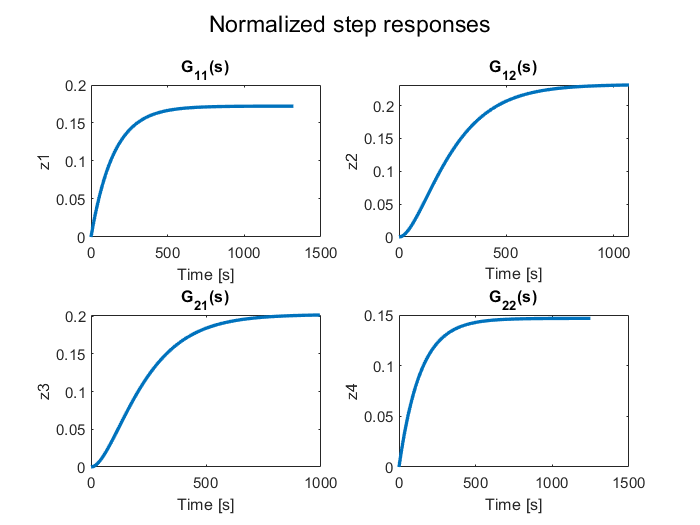

figure;
sgtitle('Normalized step responses')
subplot(2,2,1)
plot(t_G11,y_G11,"LineWidth",2)
xlabel('Time [s]'); ylabel('z1'); title('G_{11}(s)');

subplot(2,2,2)
plot(t_G12,y_G12,"LineWidth",2)
xlabel('Time [s]'); ylabel('z2'); title('G_{12}(s)');

subplot(2,2,3)
plot(t_G21,y_G21,"LineWidth",2)
xlabel('Time [s]'); ylabel('z3'); title('G_{21}(s)');

subplot(2,2,4)
plot(t_G22,y_G22,"LineWidth",2)
xlabel('Time [s]'); ylabel('z4'); title('G_{22}(s)');

Ts = 4;
Nmax = 300;
tol = 1.0e-8;

[Ad,Bd,Cd,Dd,sH]=mimoctf2dss(num,den,lambda,Ts,Nmax,tol);
H = mimodss2dimpulse(Ad,Bd,Cd,Dd,Nmax); % markove parameter;


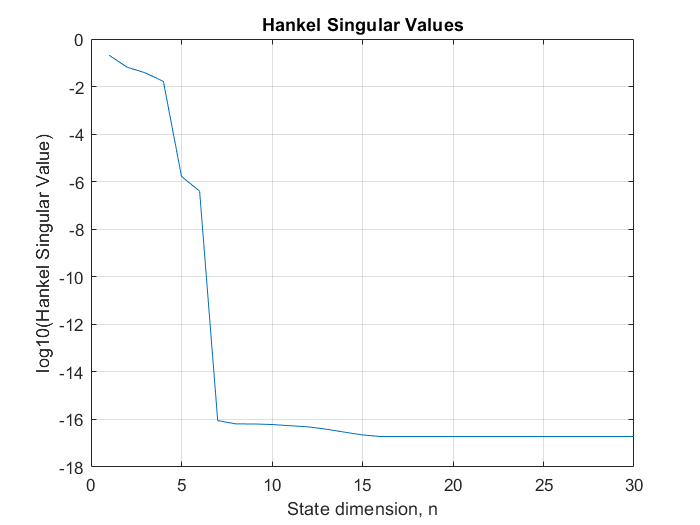

figure(9)
plot(log10(sH));grid on;
title('Hankel Singular Values')
xlabel('State dimension, n');xlim([0 30])
ylabel('log10(Hankel Singular Value)')